# Analyzing Flight Volume

Have you ever wondered how the number of flights might relate to the day of the week? For example, do more flights occur on weekdays or weekends? Let's investigate the incoming flight volume to the Boston Logan International Airport during the first month of 2015. You'll of course need to import the flights data for January 2015, "flightsJan.csv", using the importFlightsData function.

## Initial Data Import and Volume Calculation

flights = importFlightsData("flightsJan.csv");

Next extract the subset of the table with recorded incoming flights to Boston. 

flightsIntoBoston = flights(flights.DESTINATION == "BOS" , :);

Finally, calculate the incoming flight volume using the [`groupsummary`](https://www.mathworks.com/help/matlab/ref/double.groupsummary.html) function`. `Start off by using an hour for the bin size. 

flightsIntoBoston.ACTUAL_ARRIVAL_HOUR = dateshift(flightsIntoBoston.ACTUAL_ARRIVAL_TIME,"start","hour"); 
flightsIntoBostonVolume = groupsummary(flightsIntoBoston,"ACTUAL_ARRIVAL_HOUR"); 
flightsIntoBostonVolume.Properties.VariableNames = [ "Arrival_Time" "Incoming_Flights" ]; % rename the variables for convenience 

It is always a good idea to get at least a rough idea of how your data is distributed initially. Let's create a histogram for the incoming flight volume and take a look. 

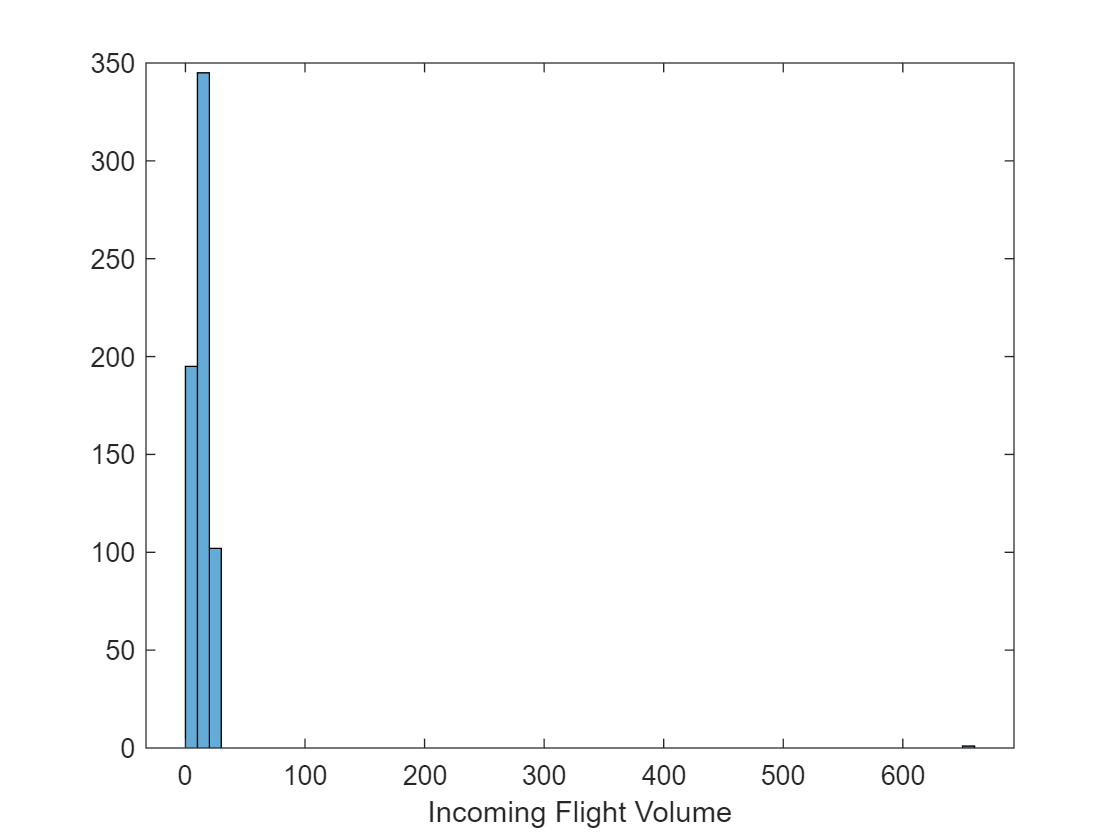

histogram(flightsIntoBostonVolume.Incoming_Flights); 
xlabel('Incoming Flight Volume'); 

It looks like the distribution is mostly in the low range, and there may be some very high data points over 600. Were there really some hours with more than 600 arriving flights? Let's investigate the corresponding times. Since we're interested in the largest data in the flights volume, let's sort the rows of the table by this variable in descending order.

sortrows(flightsIntoBostonVolume,"Incoming_Flights","descend")

ans = 643×2 table
        Arrival_Time        Incoming_Flights
    ____________________    ________________

                     NaT          659       
    15-Jan-2015 16:00:00           27       
    05-Jan-2015 16:00:00           26       
    12-Jan-2015 17:00:00           26       
    14-Jan-2015 21:00:00           26       
    21-Jan-2015 16:00:00           26       
    23-Jan-2015 17:00:00           26       
    06-Jan-2015 23:00:00           25       
    15-Jan-2015 21:00:00           25       
    16-Jan-2015 16:00:00           25       
    30-Jan-2015 20:00:00           25       
    05-Jan-2015 15:00:00           24       
    08-Jan-2015 17:00:00           24       
    13-Jan-2015 17:00:00           24       
    20-Jan-2015 17:00:00           24       
    21-Jan-2015 23:00:00           24       


### Cleaning Missing Data

You can see that the extremely high number of incoming flights corresponds to a missing entry in the time data. Most likely these "missing time flights" were due to cancelled or diverted flights which had no entry for arrival time. In any case, you can remove this data. The easiest way to do so at this point is using the [rmmissing](https://www.mathworks.com/help/matlab/ref/rmmissing.html) function. Given a table, it will remove any row with a missing entry in any variable. 

flightsIntoBostonVolume = rmmissing(flightsIntoBostonVolume)

flightsIntoBostonVolume = 642×2 table
        Arrival_Time        Incoming_Flights
    ____________________    ________________

    01-Jan-2015 06:00:00            1       
    01-Jan-2015 07:00:00            4       
    01-Jan-2015 08:00:00            4       
    01-Jan-2015 09:00:00           11       
    01-Jan-2015 10:00:00           10       
    01-Jan-2015 11:00:00            7       
    01-Jan-2015 12:00:00            9       
    01-Jan-2015 13:00:00           12       
    01-Jan-2015 14:00:00           10       
    01-Jan-2015 15:00:00           18       
    01-Jan-2015 16:00:00           22       
    01-Jan-2015 17:00:00           15       
    01-Jan-2015 18:00:00           17       
    01-Jan-2015 19:00:00           14       
    01-Jan-2015 20:00:00            9       
    01-Jan-2015 21:00:00           11       


Now that this entry is gone, let's take another look at the histogram to see if there are any other obvious issues in the data so far. 

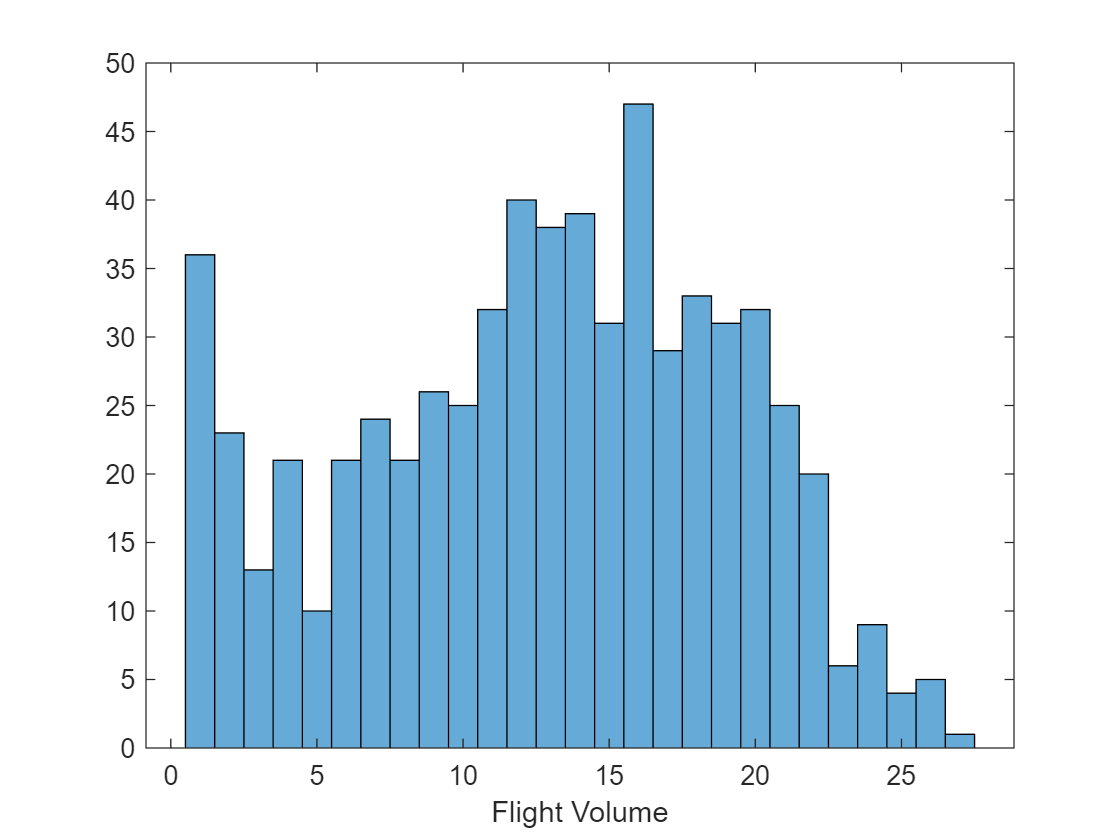

histogram(flightsIntoBostonVolume.Incoming_Flights); 
xlabel('Flight Volume'); 

It looks like the remaining numbers for flight volume are all closer together and in a more reasonable range. Since there was only one extremely large value in the incoming flight data, you could have used the [rmoutliers](https://www.mathworks.com/help/matlab/ref/rmoutliers.html) function to eliminate it. Give this a shot and verify you get the same results. ( Hint: take a look at [this](https://www.mathworks.com/help/matlab/ref/rmoutliers.html#mw_86cc5c42-1dc8-4c7c-bd8c-19fe199634f1) name/value pair. ) 

## Flight Volume vs. Weekend Status

Now you're ready to start investigating if there is any relationship between the day of the week and incoming flight volume. To get started, we'll need to add a variable to the table indicating whether or not an entry for flight volume occurred on a weekend or a weekday. Let's use the [isweekend](https://www.mathworks.com/help/matlab/ref/datetime.isweekend.html) function to accomplish this.  

flightsIntoBostonVolume.Weekend = isweekend(flightsIntoBostonVolume.Arrival_Time);

Now use [`stackedplot`](https://www.mathworks.com/help/matlab/ref/stackedplot.html) to compare the flight volume to weekend indicator with the same x-axis. 

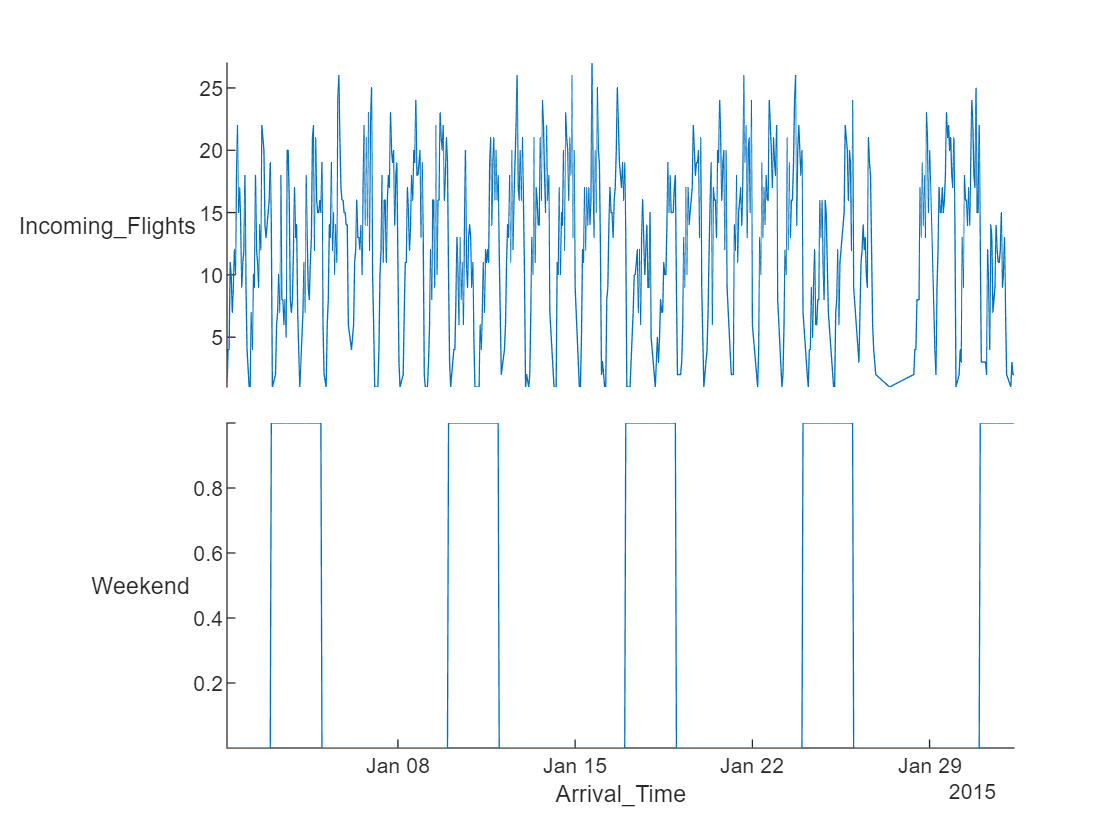

stackedplot(flightsIntoBostonVolume,"XVariable","Arrival_Time");

Taking a look at the result, it appears like there may be some spots where there is a roughly inverse relationship between flight volume and the weekend. However, this is really not very clear. Let's calculate the correlation between incoming flight volume and weekend status. 

corrVolumeWeekend = corr(flightsIntoBostonVolume.Incoming_Flights,flightsIntoBostonVolume.Weekend)

corrVolumeWeekend = -0.2521

### Smoothing Data 

A negative correlation certainly supports the idea that there may be an inverse relationship overall, but the flight volume includes a lot of short-term variation compared to the weekend indicator. Let's try smoothing the flight volume to reveal a potential relationship more fully. Start by using a centered moving median window one day in length. (Note: if you had not removed the missing entries from the table, you would get errors attempting to do this.) 

% Smooth input data
smoothedFlightVolume = smoothdata(flightsIntoBostonVolume.Incoming_Flights,...
    "movmedian",days(4.1),"SamplePoints",flightsIntoBostonVolume.Arrival_Time);


Now let's re-visualize the comparison again using [`stackedplot`](https://www.mathworks.com/help/matlab/ref/stackedplot.html)`, `but this time with the `smoothedFlightVolume` variable just created. 

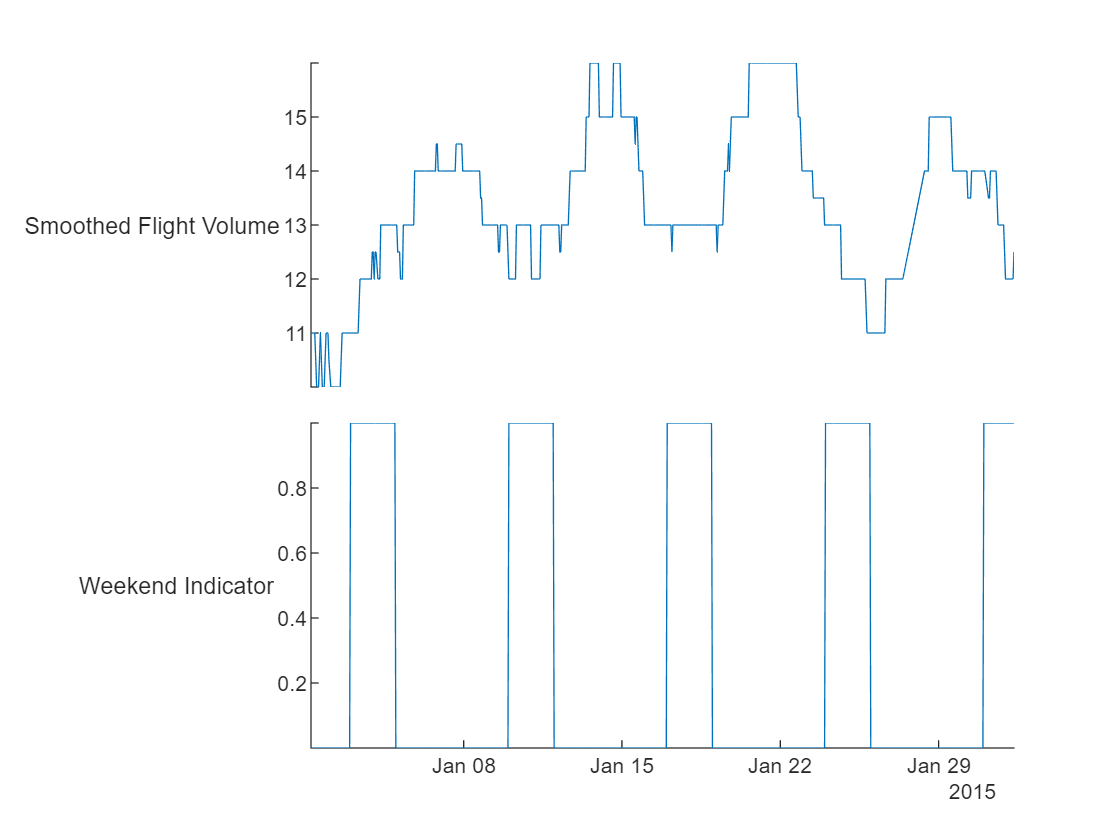

stackedplot(flightsIntoBostonVolume.Arrival_Time, [ smoothedFlightVolume , flightsIntoBostonVolume.Weekend ] ,"DisplayLabels",["Smoothed Flight Volume" "Weekend Indicator"] );

Visually, the flight volume smoothed with the one-day median window has a much clearer inverse relationship with the weekend indicator. You can also check the corresponding change in correlation coefficient.

corrSmoothVolumeWeeeknd = corr(smoothedFlightVolume,flightsIntoBostonVolume.Weekend)

corrSmoothVolumeWeeeknd = -0.3715

### Normalizing Data

Another way to visualize the relationship is by superimposing the two plots. Doing so with the previous results gives you the following figure. 

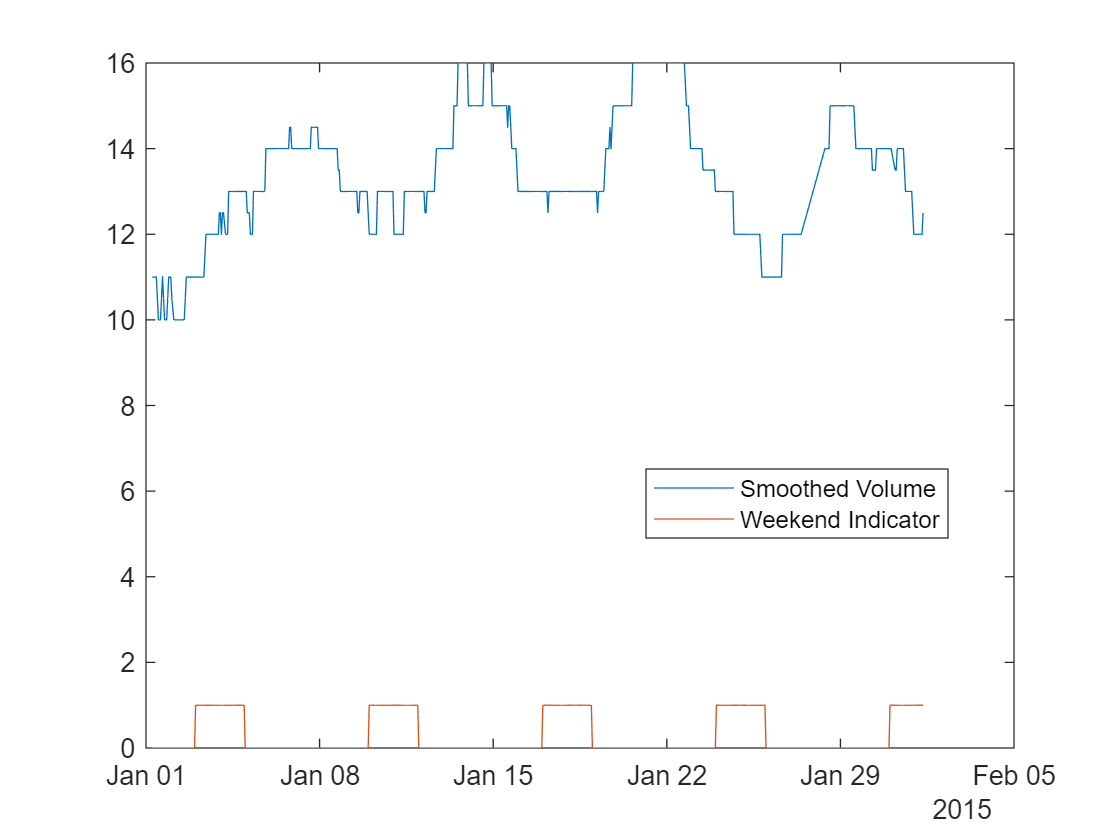

plot(flightsIntoBostonVolume.Arrival_Time,smoothedFlightVolume); 
hold on; 
plot(flightsIntoBostonVolume.Arrival_Time,flightsIntoBostonVolume.Weekend); 
hold off; 
legend(["Smoothed Volume","Weekend Indicator"],"Location","best"); 

The visualization can be significantly be improved by normalizing the volume indicator to more closely match the binary weekend indicator. 

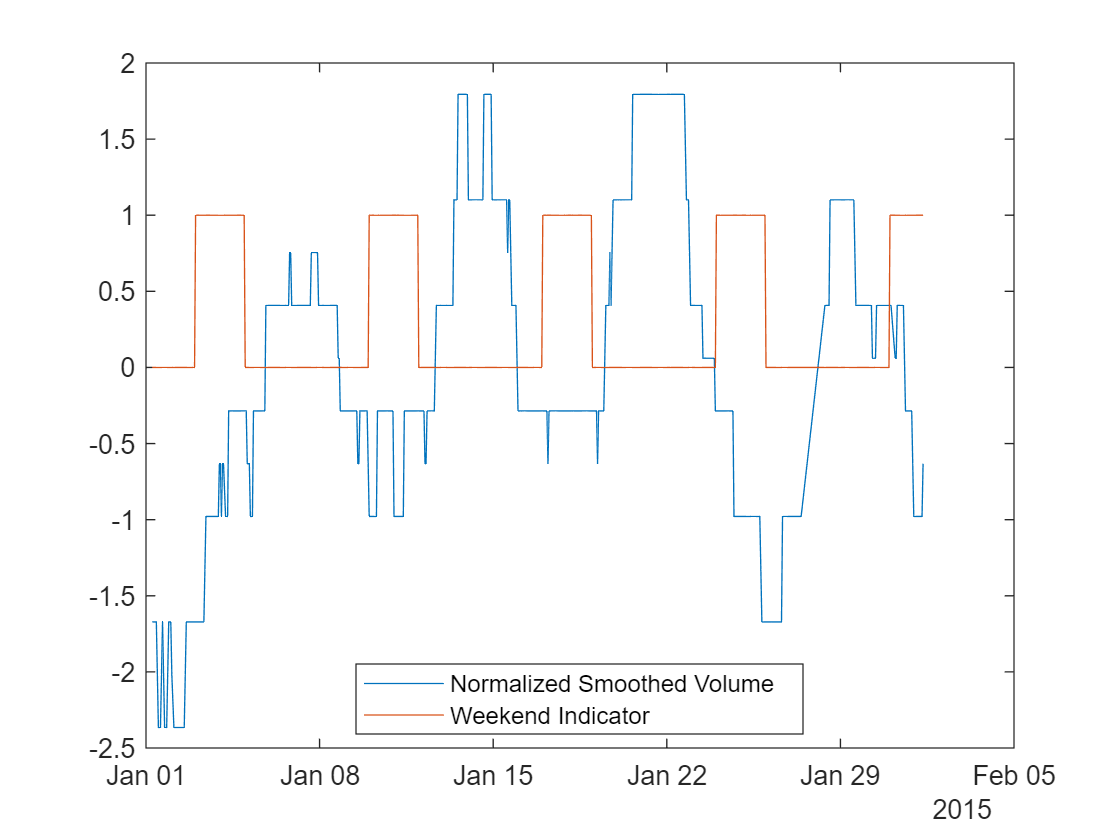

normalizedSmoothedFlightVolume = normalize(smoothedFlightVolume); 

plot(flightsIntoBostonVolume.Arrival_Time,normalizedSmoothedFlightVolume); 
hold on; 
plot(flightsIntoBostonVolume.Arrival_Time,flightsIntoBostonVolume.Weekend);
hold off; 
legend(["Normalized Smoothed Volume","Weekend Indicator"],"Location","best"); 

### Removing Outliers

You can see that almost all the time when the weekend indicator is high, the volume indicator is low, and vice versa. However, there is a notable exception to this trend around January 27th. This data point seems unusual for the volume indicator since it is far out of the typical range. Let's try identifying and removing outliers from the normalized volume indicator and comparing the remaining data to the corresponding weekend indicator again. 

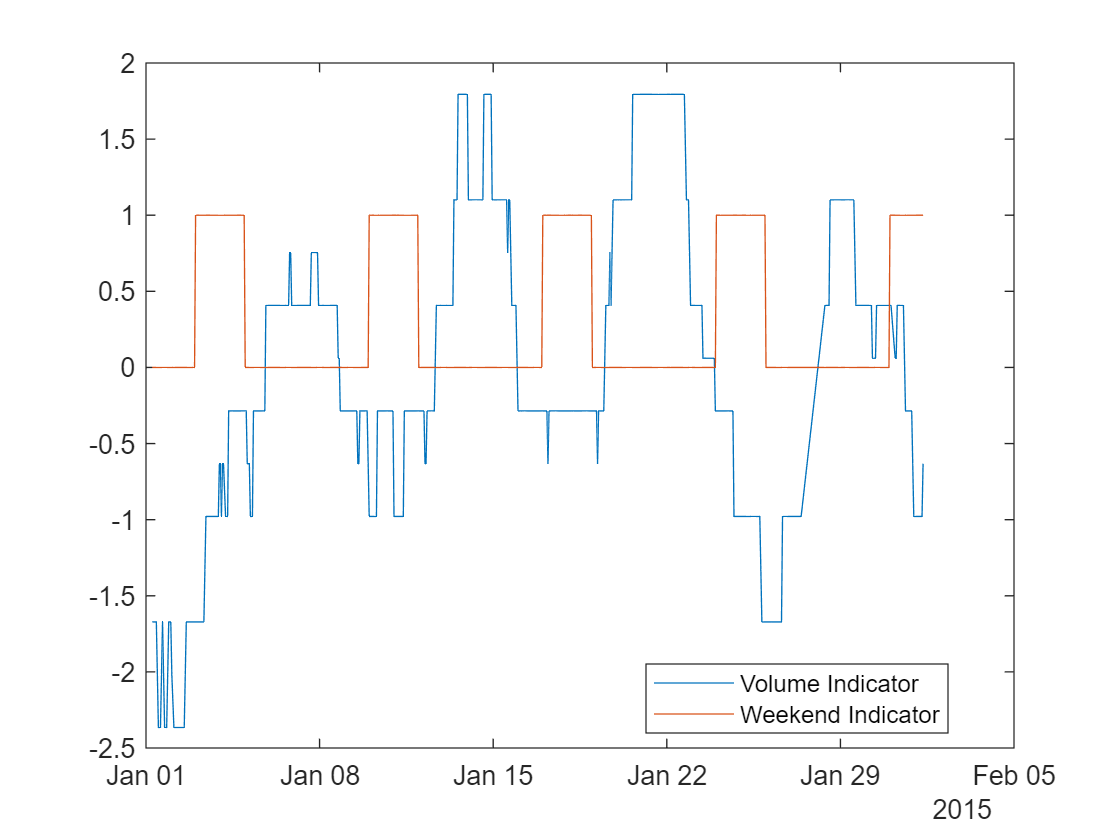

smoothedFlightVolumeOutlierIdx = isoutlier(normalizedSmoothedFlightVolume);
newSmoothedFlightVolume = normalize(smoothedFlightVolume(~smoothedFlightVolumeOutlierIdx)); 
newWeekend = flightsIntoBostonVolume.Weekend(~smoothedFlightVolumeOutlierIdx); 
newArrivalTime = flightsIntoBostonVolume.Arrival_Time(~smoothedFlightVolumeOutlierIdx); 
plot(newArrivalTime,newSmoothedFlightVolume);
hold on; 
plot(newArrivalTime,newWeekend);
hold off; 
legend(["Volume Indicator","Weekend Indicator"],"Location","best"); 

datesToKeepIdx = ( day(flightsIntoBostonVolume.Arrival_Time) < 24 | day(flightsIntoBostonVolume.Arrival_Time) > 27 );
newCorrSmoothVolumeWeeeknd = corr(newSmoothedFlightVolume,newWeekend)

newCorrSmoothVolumeWeeeknd = -0.3715

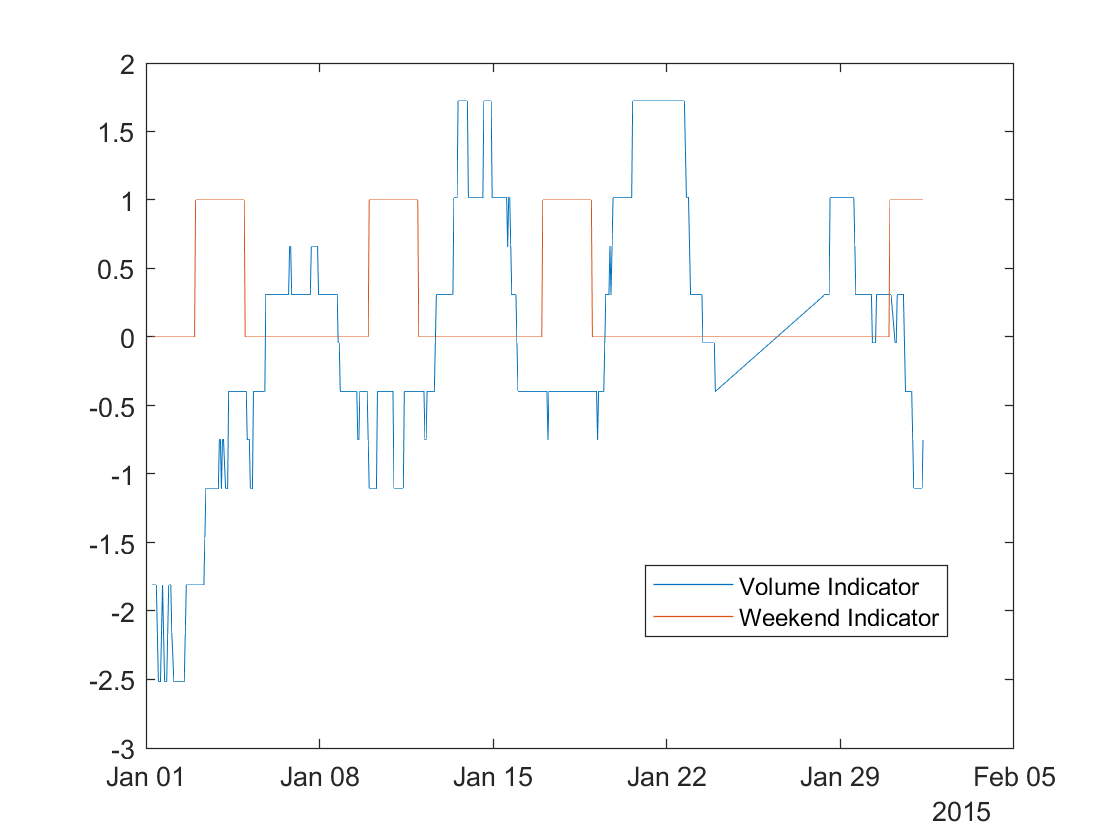

newSmoothedFlightVolume2 = normalize(smoothedFlightVolume(datesToKeepIdx)); 
newWeekend2 = flightsIntoBostonVolume.Weekend(datesToKeepIdx); 
newArrivalTime2 = flightsIntoBostonVolume.Arrival_Time(datesToKeepIdx);
figure
plot(newArrivalTime2,newSmoothedFlightVolume2);
hold on; 
plot(newArrivalTime2,newWeekend2);
hold off; 
legend(["Volume Indicator","Weekend Indicator"],"Location","best"); 

newCorrSmoothVolumeWeeeknd2 = corr(newSmoothedFlightVolume2,newWeekend2)

newCorrSmoothVolumeWeeeknd2 = -0.3669

A little increase, but not much of a difference. Looking at the figure there are still a couple obvious points that don't follow the trend around January 27th. You may recall from earlier in this module that that there was a major blizzard in the Boston area from January 26th to January 28th of 2015 [https://www.weather.gov/okx/Blizzard_01262715](https://www.weather.gov/okx/Blizzard_01262715). Maybe you can improve the result a bit more if instead of using `isoutlier` as above to determine which data to remove, you eliminate all the data from January 26th to January 28th?

## Summary

In this module you learned about missing data, outlier data, smoothing, and normalizing. Now you've seen how to combine these techniques to discover a correlation between the flight volume and day of week. This relationship was not clear at all in the raw data, but you gradually uncovered the trend through a series of cleaning steps. Of course, the particular set of steps necessary to clean your own data will be completely dependent on the scenario and your analysis goals. Don’t be afraid to try several approaches. Then, use your best judgement to select an approach that works well for data. 